clc; clear; close all;

# 1D-FC with Gram Inteprolation

Precomputing matrices at high precision for interpolation

# Error Analysis

Doing steps above on sin(pix), will assume computation matrices aren't needed, i.e. they're already given in the FC_data folder.

% fixed parameters
n_lst = [50, 100, 200];
d_lst = 3:8;
f = @(y) sin(pi*y);
C = 27;

err = zeros(length(d_lst), length(n_lst));

for i = 1:length(d_lst)
    d = d_lst(i);

    load(['FC_data/A_d',num2str(d),'_C', num2str(C), '.mat']);
    load(['FC_data/Q_d',num2str(d),'_C', num2str(C), '.mat']);
    A = double(A);
    Q = double(Q);

    for j = 1:length(n_lst)
        n = n_lst(j);
        h = 1/(n-1);
        
        x = transpose(linspace(0, 1, n));
        prd = (n+C)*h;
        [fx_cont_coeffs, ~, ~, ~] = fcont_gram_blend(f(x), d, C, A, Q, Q);
        
        x_err = transpose(linspace(0, 1, 20*n));
        err(i, j) = max(f(x_err) - FFT_compute_func(fx_cont_coeffs, prd, x_err));
    end
end
err

err = 	1.0e+-5 *

    0.5067    0.0611    0.0075
    0.0018    0.0001    0.0000
    0.0031    0.0001    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000


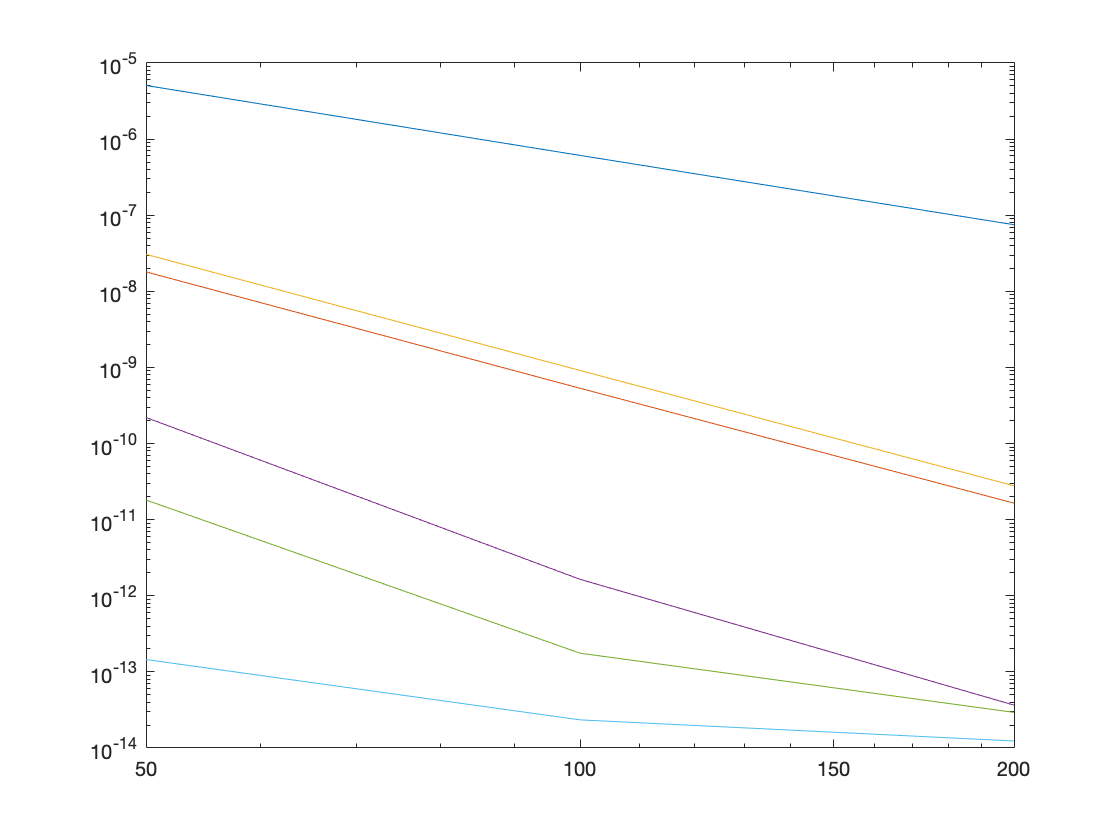

figure;
loglog(n_lst, err);


log2(err(:, 1:end-1) ./err(:, 2:end))

ans =     3.0518    3.0256
    5.0792    5.0135
    5.0676    5.0345
    7.0624    5.4917
    6.6853    2.5855
    2.6334    0.9218
